#### Conservation of energy

load('net.mat')
load('test_data1_cell.mat');
load('test_data1.mat');

net = net;

start = 16;
numSimulations = 25;
data = test_data1_cell;
data11 = test_data1;

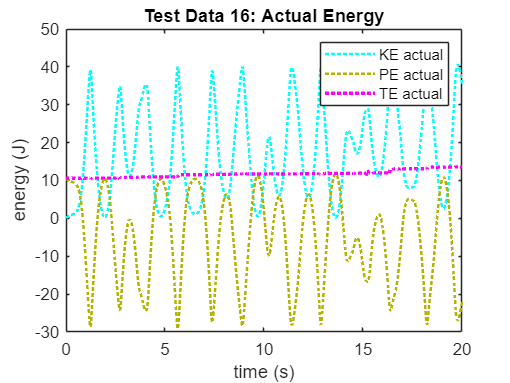

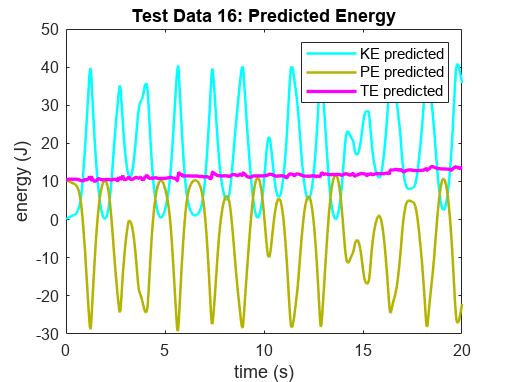

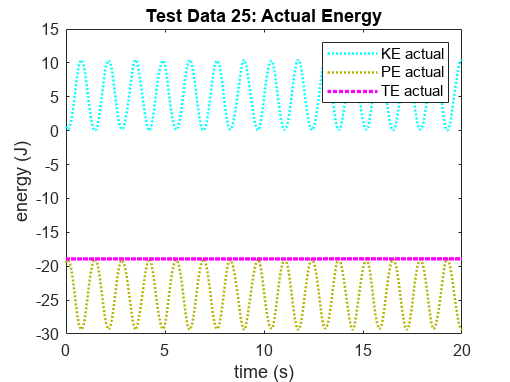

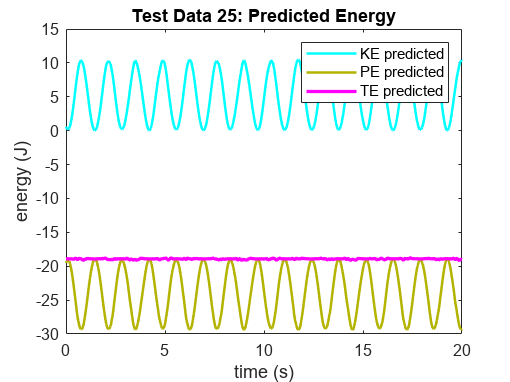

% Setting up simulation parameters
% Loop through the specified simulations
for i = [start numSimulations]
    % Extracting data for the current simulation
    time = data{i, 1};
    theta1 = data{i, 2};
    theta2 = data{i, 3};
    omega1 = data{i, 4};
    omega2 = data{i, 5};
    x1 = data{i, 6};
    y1 = data{i, 7};
    x2 = data{i, 8};
    y2 = data{i, 9};
    
     % Transposing the data 
    inputTime   = time';
    inputTheta1 = theta1';
    inputTheta2 = theta2';
    inputOmega1 = omega1';
    inputOmega2 = omega2';
    inputX1     = x1';
    inputY1     = y1';
    inputX2     = x2';
    inputY2     = y2';
    
     % Calculating kinetic, potential, and total energy from actual data
    ke = 0.5 * (m1 + m2) * (L1^2 * data11(i).omega1).^2 + 0.5 * m2 * (L2^2 * data11(i).omega2).^2 + m2 * L1 * L2 * data11(i).omega1 .* data11(i).omega2 .* cos(data11(i).theta1 - data11(i).theta2);    
    pe = -m1 * g * L1 * cos(data11(i).theta1) - m2 * g * (L1 * cos(data11(i).theta1) + L2 * cos(data11(i).theta2));  
    te = ke +pe;

     % Making predictions using the neural network
    predictedTime   = predict(net, {inputTime});
    predictedTheta1 = predict(net, {inputTheta1});
    predictedTheta2 = predict(net, {inputTheta2});
    predictedOmega1 = predict(net, {inputOmega1});
    predictedOmega2 = predict(net, {inputOmega2});
    predictedX1     = predict(net, {inputX1});
    predictedY1     = predict(net, {inputY1});
    predictedX2     = predict(net, {inputX2});
    predictedY2     = predict(net, {inputY2});

   % Converting predicted data to matrices
    newPredictedTime   = cell2mat(predictedTime);
    newPredictedTheta1 = cell2mat(predictedTheta1);
    newPredictedTheta2 = cell2mat(predictedTheta2);
    newPredictedOmega1 = cell2mat(predictedOmega1);
    newPredictedOmega2 = cell2mat(predictedOmega2);
    newPredictedX1     = cell2mat(predictedX1);
    newPredictedY1     = cell2mat(predictedY1);
    newPredictedX2     = cell2mat(predictedX2);
    newPredictedY2     = cell2mat(predictedY2);
    

    % Calculating kinetic, potential, and total energy from predicted data
    ke_from_predicted = 0.5 * (m1 + m2) * (L1 * newPredictedOmega1).^2 + 0.5 * m2 * (L2 * newPredictedOmega2).^2 + m2 * L1 * L2 * newPredictedOmega1 .* newPredictedOmega2 .* cos(newPredictedTheta1 - newPredictedTheta2);
    pe_from_predicted =-m1 * g * L1 * cos(newPredictedTheta1) - m2 * g * (L1 * cos(newPredictedTheta1) + L2 * cos(newPredictedTheta2));
    te_from_predicted = ke_from_predicted + pe_from_predicted;


    % Plotting actual total mechanical energy
     figure;        
     KE_actual = ke; 
     PE_actual = pe; 
     TE_actual = te;
     time = time;        
     plot(time, KE_actual, 'c:', 'LineWidth', 1.5);
     hold on;
     plot(time, PE_actual, 'Color', [0.7, 0.7, 0], 'LineStyle', ':', 'LineWidth', 1.5);
     plot(time, TE_actual, 'm:', 'LineWidth', 2);
    % Adding labels and title to the plot
     xlabel('time (s)');
     ylabel('energy (J)');
     title(['Test Data ', num2str(i), ': Actual Energy']);
     legend('KE actual', 'PE actual', 'TE actual'); 
     hold off;  


    % Plotting predicted total mechanical energy
     figure;        
     KE = ke_from_predicted; 
     PE = pe_from_predicted; 
     TE = te_from_predicted;
     time = time;        
     plot(time, KE, 'c', 'LineWidth', 1.5);
     hold on;
     plot(time, PE, 'Color', [0.7, 0.7, 0], 'LineWidth', 1.5);
     plot(time, TE, 'm', 'LineWidth', 2);
    % Adding labels and title to the plot
     xlabel('time (s)');
     ylabel('energy (J)');
     title(['Test Data ', num2str(i), ': Predicted Energy']);
     legend('KE predicted', 'PE predicted', 'TE predicted'); 
     hold off; 
    
    % Storing the current figure handle
    figHandles{i} = gcf;
end

% Saving all figures into a single MAT-file
save('DP_Conservation_of_energy_figures.mat', 'figHandles');

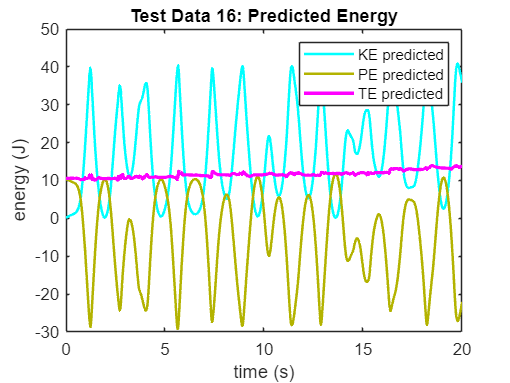

% To load the figures:
% 1. Loading the MAT-file
loadedData = load('DP_Conservation_of_energy_figures.mat');

% 2. Access the figure handles 
loadedFigHandles = loadedData.figHandles;

% 3. Display the figures
for i = [start numSimulations]
    figure(loadedFigHandles{i});
end